Consider the following system with 2 dofs


$$\ddot{x}_1+c_1\dot{x}_1+x_1+b_1x_1x_2=\epsilon f_1\cos\Omega t\\\ddot{x}_2+c_2\dot{x}_2+4x_2+b_2x_1^2=\epsilon 
f_2\cos\Omega t$$


It follows that the system has 1:2 internal resonance. Given damping coefficients $c_{1,2}$, nonlinear spring coefficients $b_{1,2}$ and forcing coefficients $f_{1,2}$, the solution manifold of such system is of two dimension and can be parameterized by $(\epsilon,\Omega)$ in general. We use this example to demonstrate

- **SSM_isol2ep**: continuation of equilibrium points in slow dynamics (corresponding to periodic orbits in regular time dynamics) in either forcing frequency $\Omega$ or forcing amplitude $\epsilon$. The continuation here starts from an initial solution (isol);

- **SSM_ep2ep**: continuation of equilibrium points in slow dynamics (corresponding to periodic orbits in regular time dynamics) in either forcing frequency $\Omega$ or forcing amplitude $\epsilon$. The continuation here starts from a saved solution to equilibrium points (ep);

- **SSM_ep2SN**: continuation of saddle-node (SN) bifurcation equilibrium points in slow dynamics (corresponding to SN bifurcation periodic orbits in regular time dynamics) in $(\Omega,\epsilon)$. The continuation here starts from a saved ep solution, which is also a SN equilibrium point;

- **SSM_ep2HB**: continuation of Hopf bifurcation (HB) equilibrium points in slow dynamics (corresponding to Neimark-Sacker or torus (TR) bifurcation periodic orbits in regular time dynamics) in $(\Omega,\epsilon)$. The continuation here starts from a saved ep solution, which is also a HB equilibrium point;

- **SSM_HB2po**: continuation of periodic orbits in slow dynamics (corresponding to tori in regular time dynamics) in either forcing frequency $\Omega$ or forcing amplitude $\epsilon$. The continuation here starts from a saved solution, which is a HB equilibrium point;

- **SSM_po2po**: continuation of periodic orbits in slow dynamics (corresponding to tori in regular time dynamics) in either forcing frequency $\Omega$ or forcing amplitude $\epsilon$. The continuation here starts from a saved periodic orbit solution;

- **SSM_po2SN**: continuation of saddle-node periodic orbits in slow dynamics (corresponding to SN tori in regular time dynamics) in $(\Omega,\epsilon)$. The continuation here starts from a saved po solution, which is also a SN periodic orbit;

- **SSM_po2PD**: continuation of periodic-doubling (PD) periorid orbits in slow dynamics (corresponding to PD tori in regular time dynamics?) in $(\Omega,\epsilon)$. The continuation here starts from a saved po solution, which is also a PD periodic orbit;

clear all

## Setup model

m = 1;
c1 = 5e-3;
c2 = 1e-2;
b1 = 1;
b2 = 1;
f1 = 1;
f2 = 0;
[mass,damp,stiff,fnl,fext] = build_model(c1,c2,b1,b2,f1,f2);


DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% Forcing
epsilon = 1e-2;
kappas = [-1; 1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();


 The first 4 eigenvalues are given as 
  -0.0025 + 1.0000i
  -0.0025 - 1.0000i
  -0.0050 + 2.0000i
  -0.0050 - 2.0000i



## SSM computation

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2 3 4]; % choose master spectral subspace
mFreq = [1 2];              % internal resonance relation vector
order = 3;                  % SSM expansion order
outdof = [1 2];             % outdof for output

### **SSM_isol2ep: continuation of equilibrium points from an initial solution**

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.18E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.95E-02 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

 Run='isol_freq_tr_cart.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES


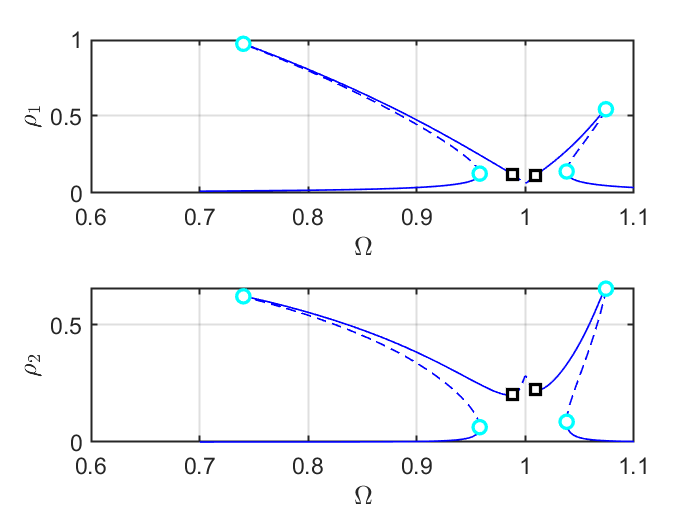

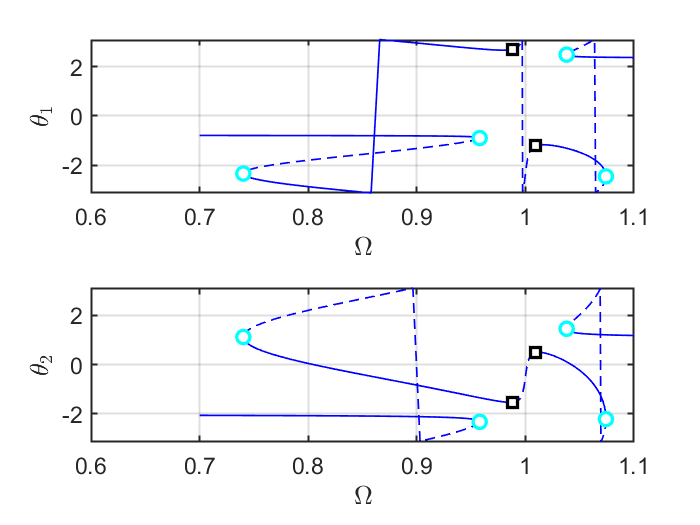

the forcing frequency 7.0000e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 7.2633e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 7.9658e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.3621e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.6146e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.7895e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 8.9181e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.0170e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.0959e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.1601e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequenc

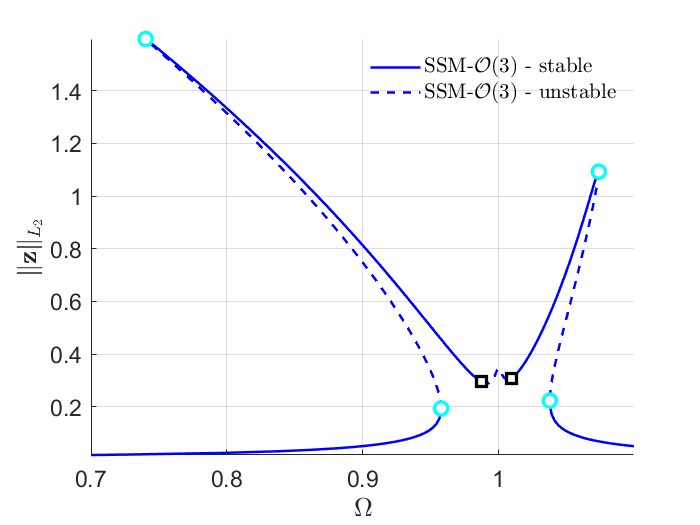

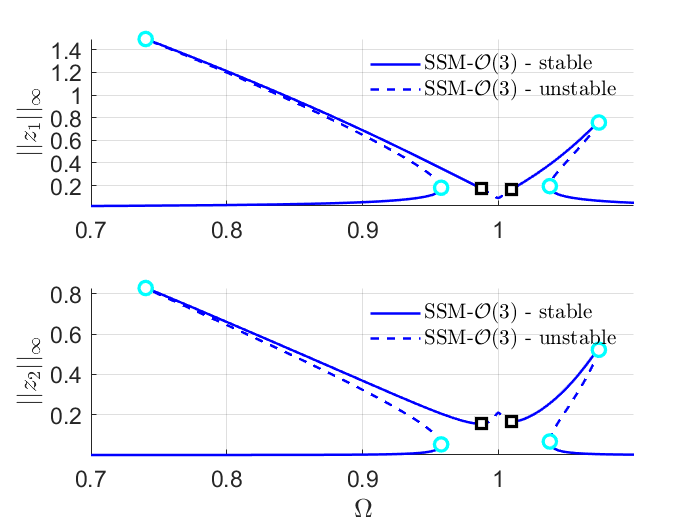

set(S.FRCOptions, 'initialSolver', 'fsolve');     % initial solution scheme
set(S.FRCOptions, 'coordinates', 'cartesian');    % coordinate representation
set(S.contOptions, 'PtMX', 200);                  % continuation setting
freqRange = [0.7 1.1]*imag(D(1));
FRC1 = S.SSM_isol2ep('isol_freq_tr_cart',resonant_modes,order,mFreq,'freq',freqRange,outdof);

### SSM_ep2HB: continuation of Hopf bifurcation equilibrium points


 Run='HB_tr_cart.ep': Continue Hopf equilibria.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.25e-09  1.75e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         Rez1         Rez2         Imz1         Imz2
    0  00:00:00   1.7502e+00      1  EP      9.8785e-01   1.0000e-02  -1.1063e-01   8.9007e-03   5.0638e-02  -2.0169e-01
    9  00:00:00   1.8472e+00      2  EP      9.6773e-01   5.0000e-02  -2.2843e-01  -1.0969e-01   1.7130e-01  -4.1531e-01

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         Rez1         Rez2         Imz1         Imz2
    0  00:00:01   1.7502e+00      3  EP      9.8785e-01   1.0000e-02  -1.1063e-01   8.9007e-03   5.0638e-02  -2.0169e-01
   10  00:00:01   1.7322e+00      4          9.9653e-01   1.6005e-03  -4.2681e-02   5.0450e-02  -6.0247e-03  -5.2990e-02
   20  00:00

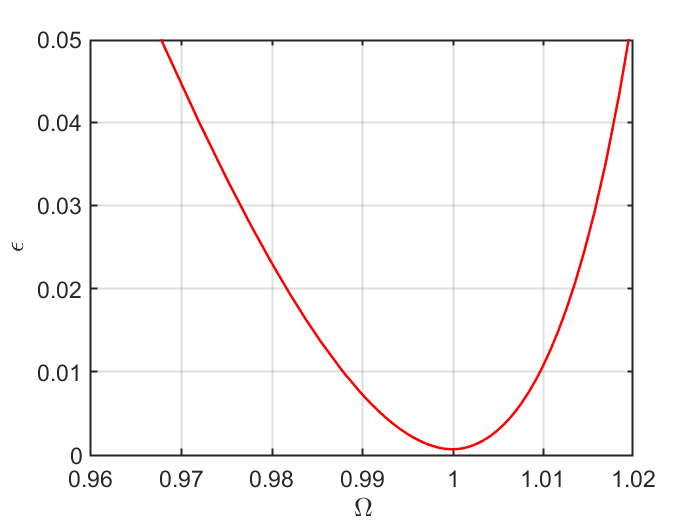

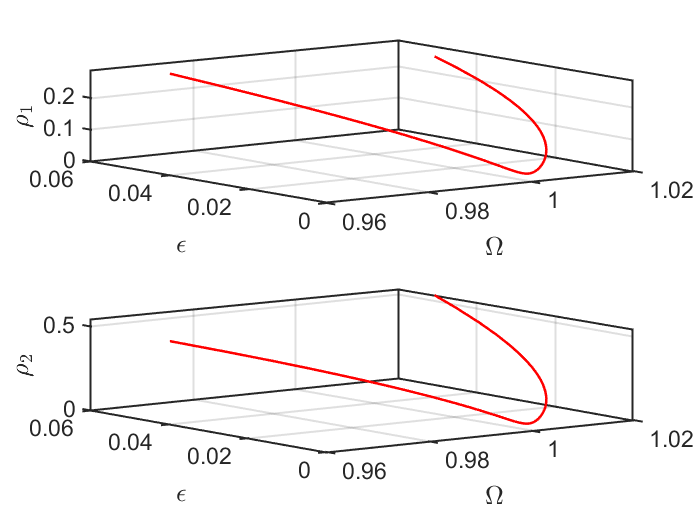

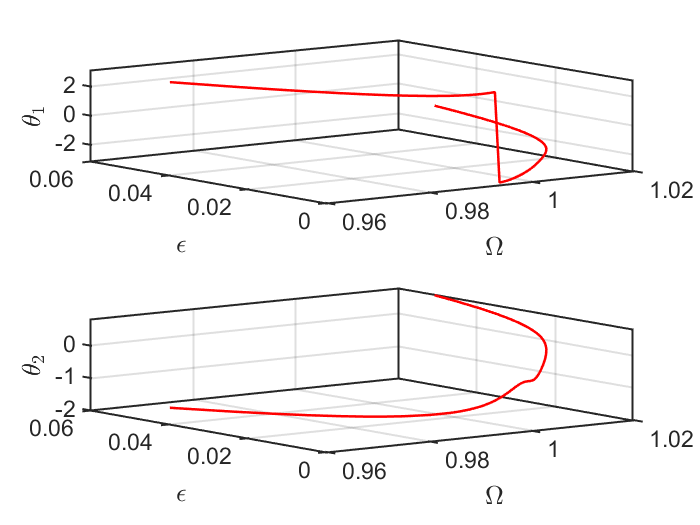

the forcing frequency 9.6773e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.6822e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.7201e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.7511e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.7770e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.7996e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.8193e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.8373e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.8539e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 9.8785e-01 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequenc

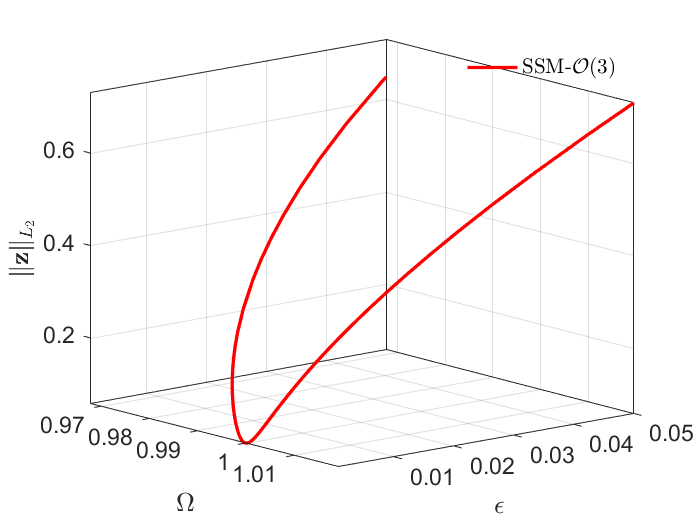

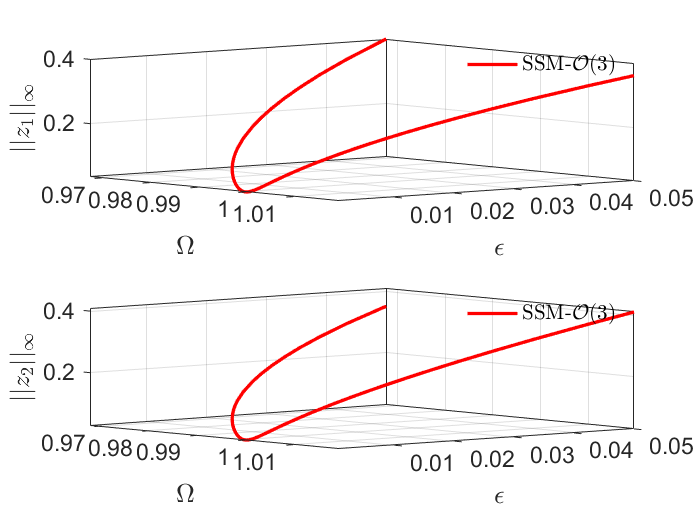

set(S.contOptions, 'h_min', 1e-3);                   % coordinate representation
epsRange = [0.01 5]*epsilon;
HBlab = 4; % or you use HBlabs = coco_bd_labs(bd, 'HB') to find it
FRC2 = S.SSM_ep2HB('HB_tr_cart','isol_freq_tr_cart',HBlab,{freqRange,epsRange},outdof);

### SSM_ep2SN: continuation of saddle-node bifurcation equilibrium points


 Run='SN_tr_cart.ep': Continue saddle-node equilibria.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          8.84e-09  2.18e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps         Rez1         Rez2         Imz1         Imz2
    0  00:00:00   2.1801e+00      1  EP      1.0741e+00   1.0000e-02  -4.2246e-01  -3.8944e-01  -3.4267e-01  -5.2441e-01
   10  00:00:01   1.7807e+00      2          1.0235e+00   2.0949e-03  -1.1888e-01  -1.0168e-01  -7.1982e-02  -9.1117e-02
   20  00:00:01   1.7499e+00      3          1.0119e+00   9.3696e-04  -6.0649e-02  -5.2295e-02  -1.8061e-02  -1.7428e-02
   30  00:00:02   1.7448e+00      4  FP      1.0096e+00   7.0614e-04  -4.3675e-02  -3.1476e-02   2.9962e-04   7.1265e-03
   30  00:00:02   1.7448e+00      5          1.0096e+00   7.0677e-04  -4.3290e-02  -3.0683e-02   9.8483e-04   7.9840e-03
   40 

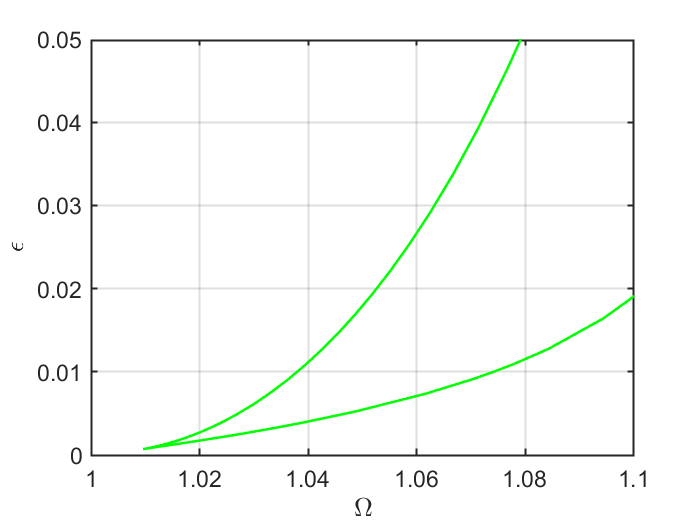

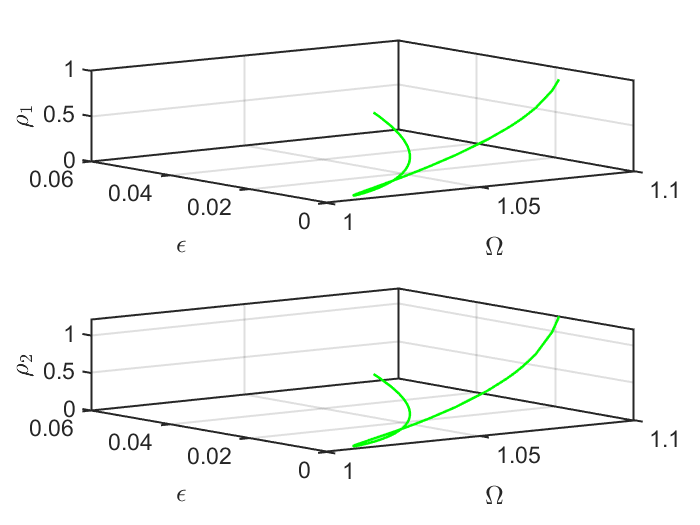

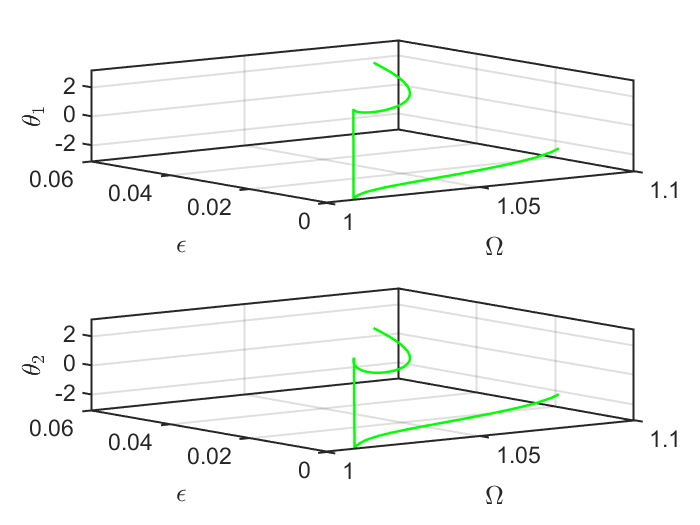

the forcing frequency 1.0792e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.0767e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.0713e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.0666e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.0624e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.0586e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.0551e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.0518e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.0487e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequency 1.0456e+00 is nearly resonant with the eigenvalue -2.5000e-03 + i1.0000e+00
the forcing frequenc

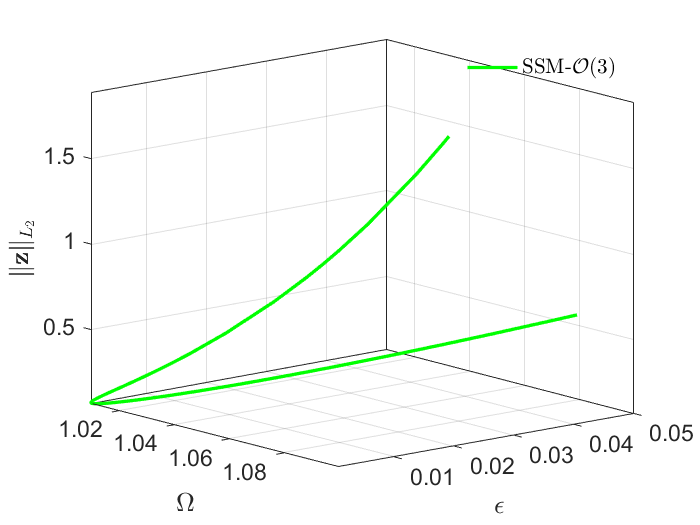

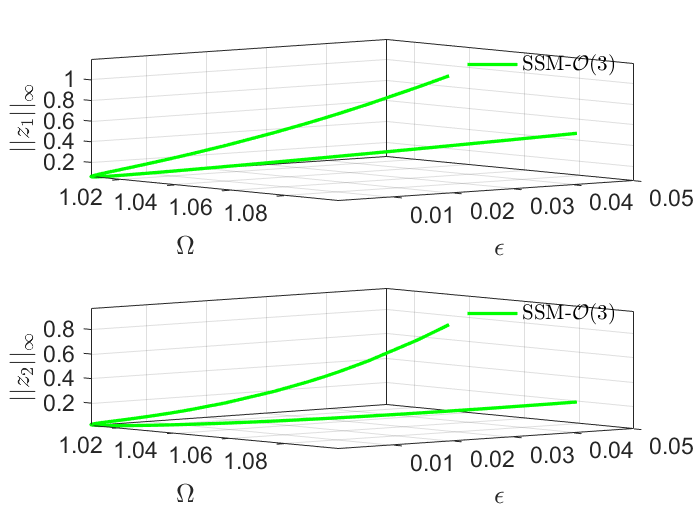

SNlab = 30; 
FRC3 = S.SSM_ep2SN('SN_tr_cart','isol_freq_tr_cart',SNlab,{freqRange,epsRange},outdof);

### SSM_HB2po: continuation of periodic orbits from HB equilibrium point


 Run='HBpo1_tr_cart.po': Continue periodic orbits born from HB point.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          6.79e-06  2.74e+02    0.0    0.0    0.0
   1   1  1.00e+00  1.61e-03  8.86e-08  2.74e+02    0.0    0.0    0.0
   2   1  1.00e+00  2.84e-05  2.77e-11  2.74e+02    0.0    0.0    0.0
   3   1  1.00e+00  7.35e-08  4.81e-15  2.74e+02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period          eps
    0  00:00:00   2.7394e+02      1  EP      9.8785e-01   1.9370e+02   1.0000e-02
   10  00:00:01   2.7399e+02      2          9.8786e-01   1.9374e+02   1.0000e-02
   18  00:00:02   2.7878e+02      3  UZ      9.8800e-01   1.9712e+02   1.0000e-02
   20  00:00:02   2.9013e+02      4          9.8831e-01   2.0514e+02   1.0000e-02
   27  00:00:03   3.2124e+02      5  SN      9.8877e-01   2.2715e+02   1.0000e-02
   30  00:00:04

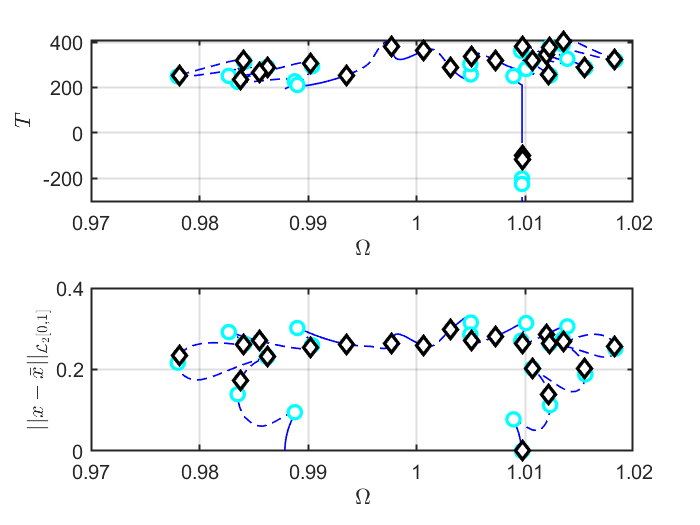

Constructing torus in reduced dynamical system
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.870000e-01
Interpolation at frequency 9.860000e-01
Interpolation at frequency 9.850000e-01
Interpolation at frequency 9.840000e-01
Interpolation at frequency 9.840000e-01
Interpolation at frequency 9.850005e-01
Interpolation at frequency 9.860000e-01
Interpolation at frequency 9.860000e-01
Interpolation at frequency 9.850000e-01
Interpolation at frequency 9.840000e-01
Interpolation at frequency 9.830000e-01
Interpolation at frequency 9.820000e-01
Interpolation at frequency 9.810000e-01
Interpolation at frequency 9.800000e-01
Interpolation at frequency 9.790002e-01
Interpolation at frequency 9.780000e-01
Interpolation at frequency 9.780000e-01
Interpolation at frequency 9.790000e-01
Interpolation at frequency 9.800000e-01
Interpolation at frequency 9.810000e-01
Interpolation at frequency 9.819995e-01
Interpolation at frequency 9.830000e-01
Interpolation at frequency 9.8400

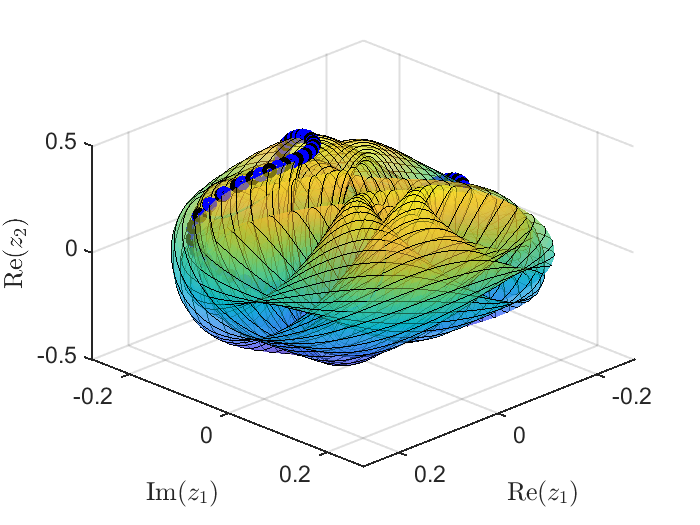

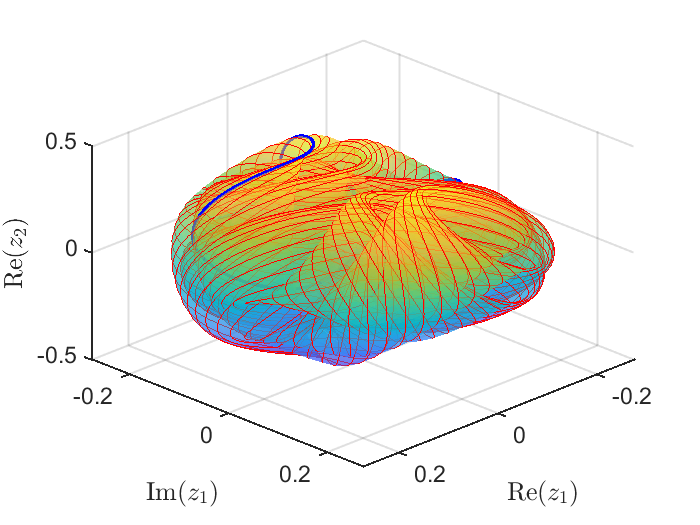


 FRCs from ='HBpo1_tr_cart.po': generating torus in physical domain.


set(S.contOptions, 'NAdapt', 2, 'PtMX', 1500, 'h_max', 5, 'bi_direct', false);
set(S.FRCOptions, 'sampStyle', 'uniform');
set(S.FRCOptions, 'nPar', 51);
S.SSM_HB2po('HBpo1_tr_cart','isol_freq_tr_cart',HBlab,'freq',[0.97 1.02],outdof,'saveICs');

#### FRC of quasi-periodic orbits in physical coordinates

bd   = coco_bd_read('HBpo1_tr_cart.po');
labs = coco_bd_labs(bd, 'UZ');
nlab = numel(labs);
om = zeros(nlab,1);
Tp  = zeros(nlab,1);
x1amp = zeros(nlab,1); % amplitude of x1(t)
st = false(nlab,1);
x0 = cell(nlab,1);     % cross section of torus at t=0
for i=1:nlab
    sol = SSM_po_read_solution('HBpo1_tr_cart',labs(i));
    om(i) = sol.om;
    Tp(i) = sol.Tpo;
    x1i   = sol.xTr(:,1,:);
    x1amp(i) = norm(x1i(:),'inf');
    st(i) = sol.st;
    xx = permute(sol.xTr, [2,3,1]);
    x0{i} = xx(:,:,1);
end

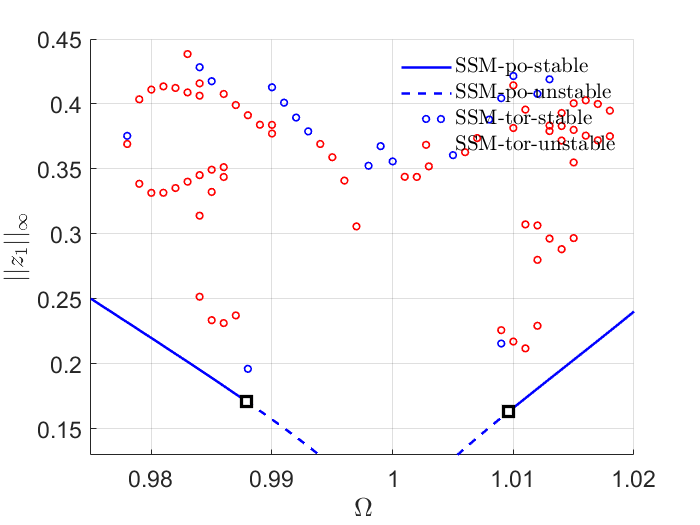

ST = cell(2,1);
ST{1} = {'b--','LineWidth',1.5}; % unstable
ST{2} = {'b-','LineWidth',1.5};  % stable
legs = 'SSM-$\mathcal{O}(3)$-unstable';
legu = 'SSM-$\mathcal{O}(3)$-stable';
thm = struct();
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};

figure; hold on
plot_stab_lines(FRC1.om,FRC1.Aout_frc(:,1),FRC1.st,ST,legs,legu);
SNidx = FRC1.SNidx;
HBidx = FRC1.HBidx;
SNfig = plot(FRC1.om(SNidx),FRC1.Aout_frc(SNidx,1),thm.SN{:});
set(get(get(SNfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');
HBfig = plot(FRC1.om(HBidx),FRC1.Aout_frc(HBidx,1),thm.HB{:});
set(get(get(HBfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');   
plot(om(st),x1amp(st),'bo','LineWidth',1,'MarkerSize',4); hold on
plot(om(~st),x1amp(~st),'ro','LineWidth',1,'MarkerSize',4); hold on
leg = legend('SSM-po-stable','SSM-po-unstable',...
    'SSM-tor-stable','SSM-tor-unstable','Interpreter','latex');
legend boxoff
xlabel('$\Omega$','Interpreter','latex'); 
ylabel('$||z_1||_{\infty}$','Interpreter','latex'); 
set(gca,'FontSize',14);
grid on, axis tight; legend boxoff;

axis([0.975,1.02,0.13,0.45])

### SSM_po2po: continuation of periodic orbits from saved solution


 Run='po2.po': Continue periodic orbits from label 3 of run HBpo1_tr_cart.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.57e-15  2.79e+02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period           om
    0  00:00:00   2.7877e+02      1  EP      1.0000e-02   1.9712e+02   9.8800e-01
    5  00:00:01   2.7714e+02      2  SN      9.8236e-03   1.9597e+02   9.8800e-01
    6  00:00:01   2.7614e+02      3  BP      1.0001e-02   1.9526e+02   9.8800e-01
   10  00:00:02   2.6008e+02      4          1.0001e-02   1.8390e+02   9.8800e-01
   12  00:00:03   2.5424e+02      5  SN      1.0001e-02   1.7977e+02   9.8800e-01
   20  00:00:03   2.1008e+02      6          1.0001e-02   1.4854e+02   9.8800e-01
   30  00:00:04   1.6008e+02      7          1.0001e-02   1.1319e+02   9.8800e-01
   40  00:00:04   1.1008e+02      8          1.0001e-02 

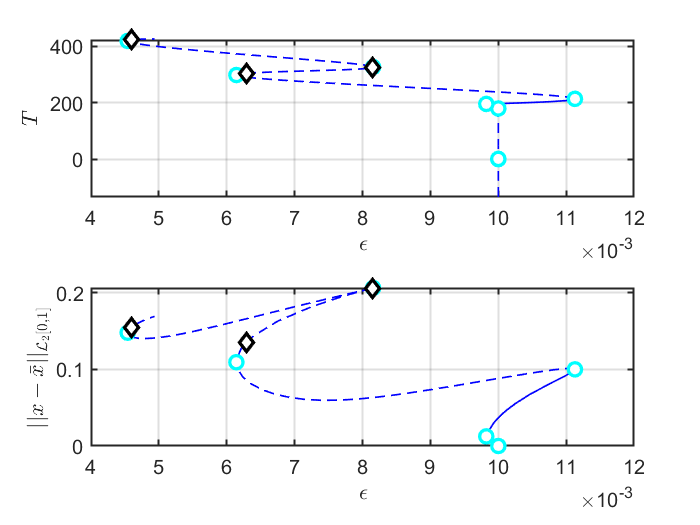

Constructing torus in reduced dynamical system
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.880000e-01
Interpolation at frequency 9.8800

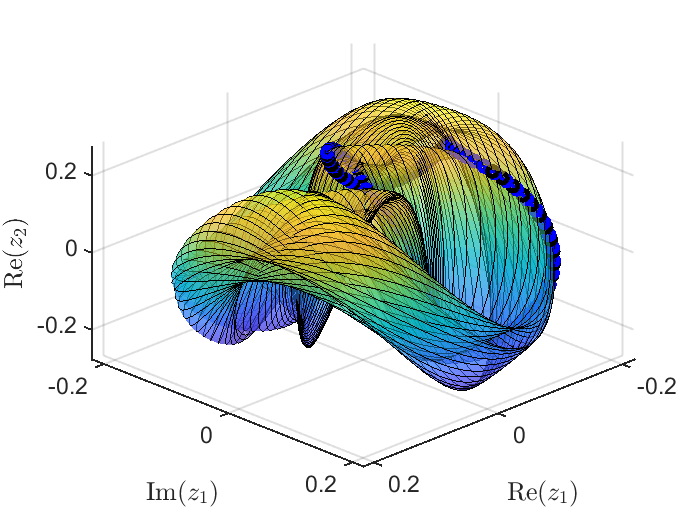

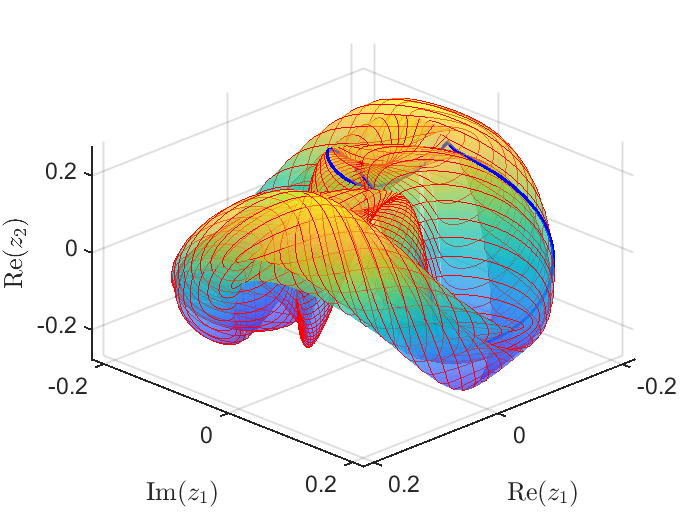


 FRCs from ='po2.po': generating torus in physical domain.


set(S.contOptions, 'NAdapt', 2, 'PtMX', 100, 'h_max', 5, 'bi_direct', true);
set(S.FRCOptions, 'sampStyle', 'cocoBD');
LAB = 3;
S.SSM_po2po('po2','HBpo1_tr_cart',LAB, 'amp', epsRange, outdof, 'saveICs');

### SSM_HB2po under variation of $\epsilon$


 Run='HBpo2_tr_cart.po': Continue periodic orbits born from HB point.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          6.30e-06  1.14e+02    0.0    0.0    0.0
   1   1  1.00e+00  4.46e-05  1.29e-12  1.14e+02    0.0    0.0    0.0
   2   1  1.00e+00  5.40e-09  2.48e-15  1.14e+02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period           om
    0  00:00:00   1.1400e+02      1  EP      5.0000e-02   8.0568e+01   9.6773e-01
   10  00:00:01   1.1416e+02      2          5.0191e-02   8.0690e+01   9.6773e-01
   20  00:00:01   1.1695e+02      3          5.2876e-02   8.2644e+01   9.6773e-01
   24  00:00:02   1.1849e+02      4  PD      5.4011e-02   8.3732e+01   9.6773e-01
   26  00:00:03   1.1968e+02      5  PD      5.4684e-02   8.4559e+01   9.6773e-01
   30  00:00:03   1.2193e+02      6          5.5519e-02   8.6153e+01   9.6773e-01
   

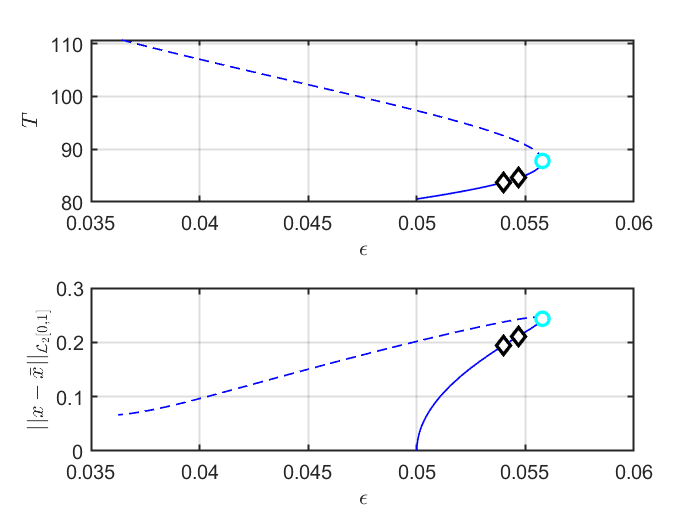

Constructing torus in reduced dynamical system
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Illustration of the construction of torus in reduced dynamical system
Visualization of toru at frequency 9.677295e-01


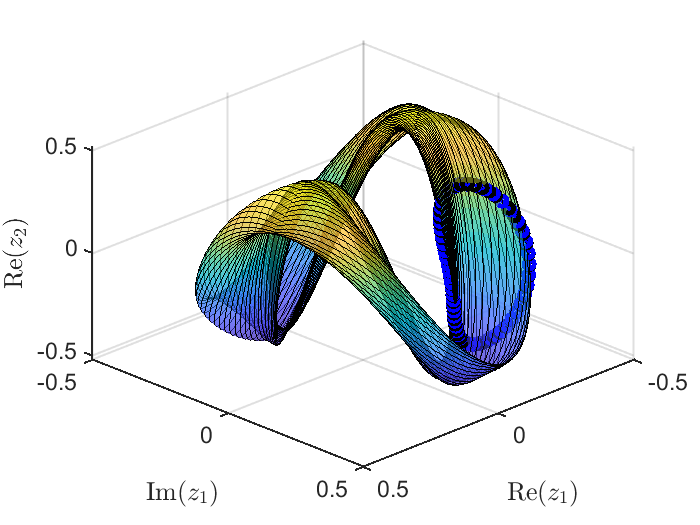

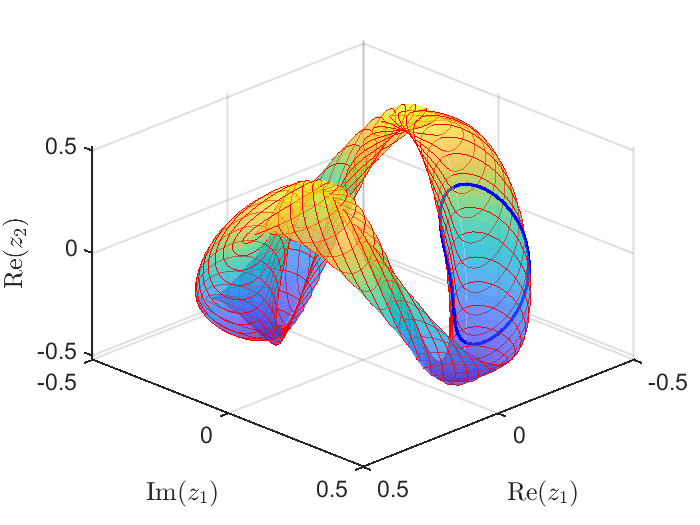


 FRCs from ='HBpo2_tr_cart.po': generating torus in physical domain.


set(S.contOptions, 'PtMX', 100, 'h_max', 0.5, 'bi_direct', false);
epsRange = [0.01 10]*epsilon;
S.SSM_HB2po('HBpo2_tr_cart','HB_tr_cart',2,'amp',epsRange,outdof,'saveICs');

### SSM_po2SN: continuation of Saddle-Node bifurcation periodic orbits


 Run='SN.po': Continue SN periodic orbits from label 7 of run HBpo2_tr_cart.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.40e-04  4.56e+02    0.0    0.0    0.0
   1   2  5.00e-01  3.17e-01  1.54e-04  4.56e+02    0.0    0.0    0.0
   2   1  1.00e+00  1.51e-01  9.68e-05  4.56e+02    0.0    0.0    0.0
   3   1  1.00e+00  3.61e-03  4.50e-07  4.56e+02    0.0    0.1    0.0
   4   1  1.00e+00  2.66e-05  4.04e-07  4.56e+02    0.0    0.1    0.0
   5   1  1.00e+00  1.66e-05  4.50e-07  4.56e+02    0.0    0.1    0.0
   6   1  1.00e+00  3.21e-06  4.51e-07  4.56e+02    0.1    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps    po.period
    0  00:00:00   4.5639e+02      1  EP      9.6773e-01   5.5795e-02   8.7768e+01
   10  00:00:01   4.6046e+02      2          9.6787e-01   5.5396e-02   8.8121e+01
   20  00:00:04   4.6537e+02      3         

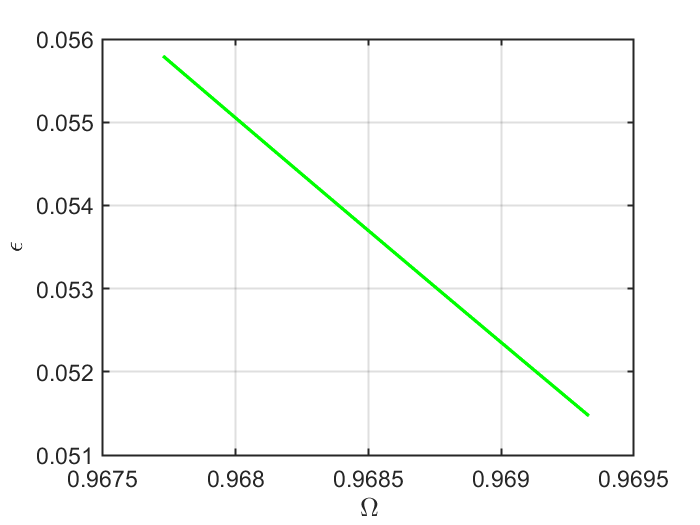

Constructing torus in reduced dynamical system
Interpolation at frequency 9.677264e-01
Interpolation at frequency 9.678728e-01
Interpolation at frequency 9.680465e-01
Interpolation at frequency 9.682173e-01
Interpolation at frequency 9.683853e-01
Interpolation at frequency 9.685506e-01
Interpolation at frequency 9.687043e-01
Interpolation at frequency 9.688645e-01
Interpolation at frequency 9.690222e-01
Interpolation at frequency 9.691774e-01
Interpolation at frequency 9.693302e-01
Illustration of the construction of torus in reduced dynamical system
Visualization of toru at frequency 9.677264e-01


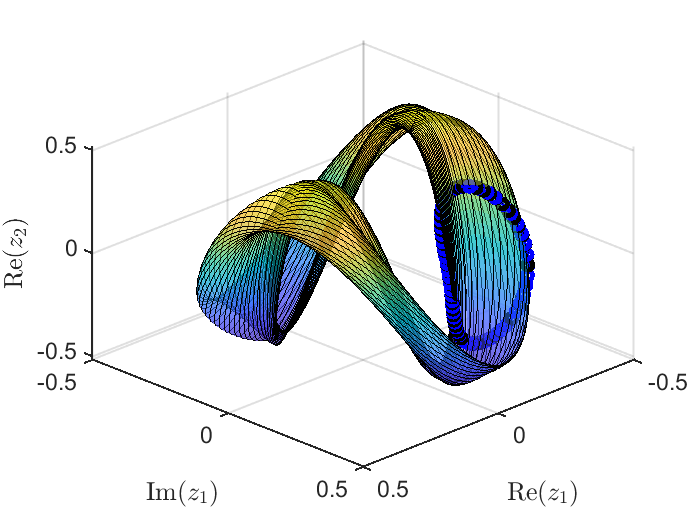

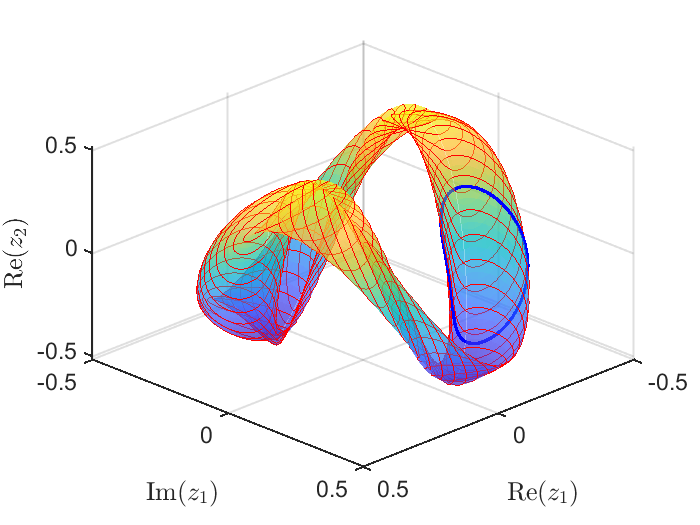


 FRCs from ='SN.po': generating torus in physical domain.


SNLAB = 7; 
set(S.contOptions, 'TOL', 1e-5);
epsRange = [2 8]*epsilon;
S.SSM_po2SN('SN','HBpo2_tr_cart',SNLAB,{freqRange,epsRange},outdof,'saveICs');

### SSM_po2PD: continuation of Period-doubling bifurcation periodic orbits


 Run='PD.po': Continue PD periodic orbits from label 4 of run HBpo2_tr_cart.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.78e-07  1.20e+02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om          eps    po.period
    0  00:00:00   1.1982e+02      1  EP      9.6773e-01   5.4011e-02   8.3732e+01
   10  00:00:02   1.1669e+02      2          9.6676e-01   5.6504e-02   8.1490e+01
   20  00:00:05   1.1186e+02      3          9.6514e-01   6.0760e-02   7.8049e+01
   30  00:00:06   1.0696e+02      4          9.6332e-01   6.5652e-02   7.4567e+01
   40  00:00:09   1.0261e+02      5          9.6154e-01   7.0565e-02   7.1474e+01
   50  00:00:11   9.7699e+01      6          9.5931e-01   7.6848e-02   6.7989e+01
   56  00:00:12   9.5883e+01      7  EP      9.5822e-01   8.0000e-02   6.6406e+01

 STEP      TIME        ||U||  LABEL  TYPE            

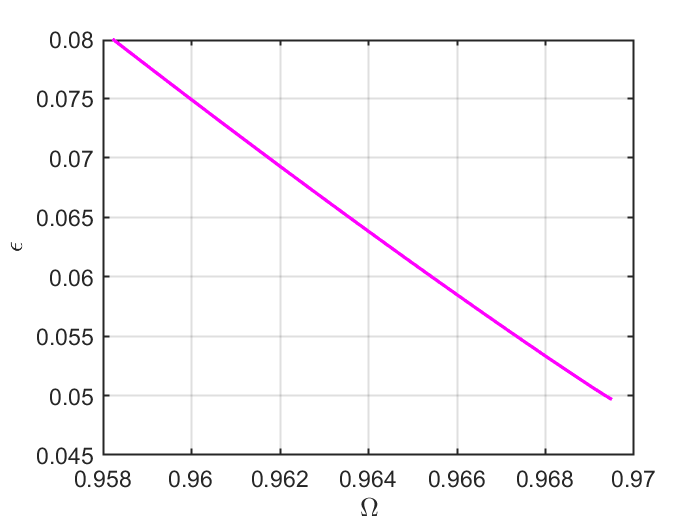

Constructing torus in reduced dynamical system
Interpolation at frequency 9.582152e-01
Interpolation at frequency 9.593141e-01
Interpolation at frequency 9.615423e-01
Interpolation at frequency 9.633247e-01
Interpolation at frequency 9.651403e-01
Interpolation at frequency 9.667598e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.677295e-01
Interpolation at frequency 9.686127e-01
Interpolation at frequency 9.691559e-01
Interpolation at frequency 9.692088e-01
Interpolation at frequency 9.692887e-01
Interpolation at frequency 9.695019e-01
Interpolation at frequency 9.695019e-01
Illustration of the construction of torus in reduced dynamical system
Visualization of toru at frequency 9.582152e-01


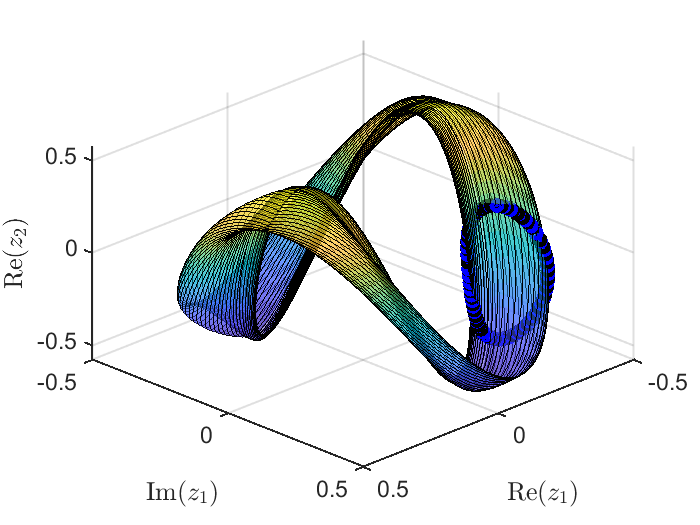

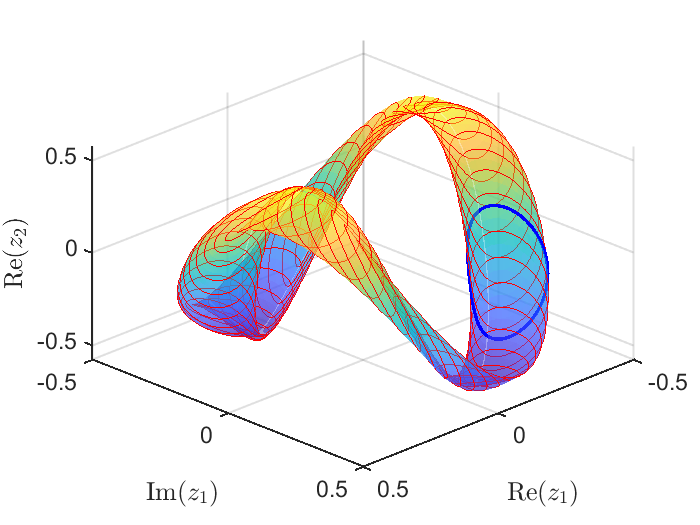


 FRCs from ='PD.po': generating torus in physical domain.


PDLAB = 4; 
set(S.contOptions, 'h_min', 0.01, 'bi_direct', true, 'TOL', 1e-6);
S.SSM_po2PD('PD','HBpo2_tr_cart',PDLAB,{freqRange,epsRange},outdof,'saveICs');